%% 62743 DSP — Week 12 Torsdag
% Under-Sampling of Passband Signals (Bandpass Sampling)
clear; close all; clc;

% Add helper functions to path (plot_spectrum.m lives here)
addpath('..\Helpers');

%% ---------- Global parameters & helper switches ----------
Fdata_default    = 1000;    % [Hz]
Fcarrier_default = 16000;   % [Hz]
B_default        = 4000;    % [Hz]  % bandwidth

% Directory for saving figures (edit if needed)
imgDir   = 'C:\Users\Mads2\DTU\Obsidian\Courses\DSP\Images\Week12_Torsdag';
saveFigs = true;            % Set false to skip saving

if saveFigs && ~exist(imgDir,'dir')
    mkdir(imgDir);
end

% Small helper: Hz -> kHz
make_khz = @(f_hz) f_hz/1000;



## Exercise 1-A: Time-domain expression (positive & negative frequencies)

Fdata    = Fdata_default;
Fcarrier = Fcarrier_default;

fprintf('Exercise 1-A:\n');

Exercise 1-A:


fprintf('  F_data    = %.0f Hz\n', Fdata);

  F_data    = 1000 Hz


fprintf('  F_carrier = %.0f Hz\n', Fcarrier);

  F_carrier = 16000 Hz




F1 = Fcarrier - Fdata;   % lower sideband
F2 = Fcarrier + Fdata;   % upper sideband

fprintf('  Frequencies from product-to-sum:\n');

  Frequencies from product-to-sum:


fprintf('    F_carrier - F_data = %.0f Hz\n', F1);

    F_carrier - F_data = 15000 Hz


fprintf('    F_carrier + F_data = %.0f Hz\n', F2);

    F_carrier + F_data = 17000 Hz


fprintf('  Complex exponentials at: +/-%.0f Hz, +/-%.0f Hz (amp = 0.25)\n\n', F1, F2);

  Complex exponentials at: +/-15000 Hz, +/-17000 Hz (amp = 0.25)



## Exercise 1-B: Analog spectrum sketch (impulses) — using plot_spectrum

Fdata    = Fdata_default;
Fcarrier = Fcarrier_default;

F1 = Fcarrier - Fdata;   % 15 kHz
F2 = Fcarrier + Fdata;   % 17 kHz

fprintf('Exercise 1-B:\n');

Exercise 1-B:


fprintf('  Impulse locations: F = {-%.0f, -%.0f, %.0f, %.0f} Hz\n\n', F2, F1, F1, F2);

  Impulse locations: F = {-17000, -15000, 15000, 17000} Hz



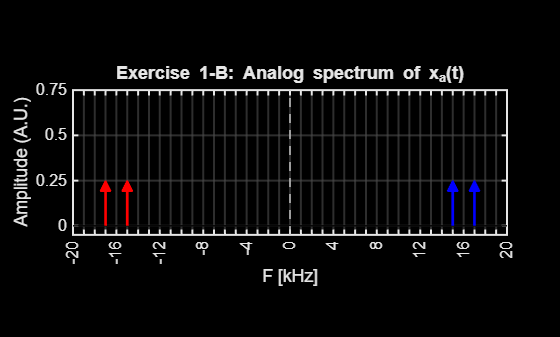


% plot
freqs_khz = make_khz([-F2, -F1, F1, F2]);
amps      = 0.25 * ones(1,4);

fig_b = plot_spectrum(freqs_khz, amps, ...
    'XRange', [-20 20], ...
    'XStep', 1, ...
    'MaxXLabels', 11, ...   % e.g. labels every ~4 kHz
    'YMax', 0.75, ...
    'YStep', 0.25, ...
    'MaxYLabels', 4, ...
    'XLabel', 'F [kHz]', ...
    'YLabel', 'Amplitude (A.U.)', ...
    'Title', 'Exercise 1-B: Analog spectrum of x_a(t)', ...
    'Colors', {{'r'}, {'r'}, {'b'}, {'b'}});

figure(fig_b); hold on;
xline(0, '--', 'LineWidth', 1.5, 'Color', [0.8 0.8 0.8]);
hold off;

if saveFigs
    exportgraphics(fig_b, fullfile(imgDir,'DSP_U12_Torsdag_1B_analog_spectrum.png'),'Resolution',300);
end

## Exercise 1-C: Minimum sampling frequency (no aliasing)

fprintf('Exercise 1-C:\n');

Exercise 1-C:


Fmax   = Fcarrier + Fdata;        % 17 kHz
Fs_min = 2*Fmax;                  % 34 kHz

fprintf('  F_max  = F_carrier + F_data = %.0f Hz\n', Fmax);

  F_max  = F_carrier + F_data = 17000 Hz


fprintf('  Fs_min = 2 * F_max = %.0f Hz (Nyquist, no aliasing)\n\n', Fs_min);

  Fs_min = 2 * F_max = 34000 Hz (Nyquist, no aliasing)



## Exercise 1-D: Integer band positioning for under-sampling

fprintf('Exercise 1-D:\n');

Exercise 1-D:



B   = B_default;            % 4 kHz
FL  = Fcarrier;             % lower band edge
FH  = FL + B;               % upper band edge
FsD = 2*B;                  % 2B
m   = FH / B;

fprintf('  B   = %.0f Hz\n', B);

  B   = 4000 Hz


fprintf('  FL  = F_carrier = %.0f Hz\n', FL);

  FL  = F_carrier = 16000 Hz


fprintf('  FH  = FL + B    = %.0f Hz\n', FH);

  FH  = FL + B    = 20000 Hz


fprintf('  Fs  = 2B        = %.0f Hz\n', FsD);

  Fs  = 2B        = 8000 Hz


fprintf('  m   = FH/B      = %.1f  --> integer? %s\n', m, string(abs(m-round(m))<1e-10));

  m   = FH/B      = 5.0  --> integer? true


if mod(round(m),2)==1
    fprintf('  m is odd  --> non-inverted baseband alias.\n\n');
else
    fprintf('  m is even --> inverted baseband alias.\n\n');
end

  m is odd  --> non-inverted baseband alias.



## Exercise 1-E: Under-sampled spectrum for Fs = 2B (full aliases)

fprintf('Exercise 1-E:\n');
fprintf('  With Fs = 2B = %.0f Hz and integer band positioning, EVERY alias\n', FsD);

  With Fs = 2B = 8000 Hz and integer band positioning, EVERY alias


fprintf('  line is the sum of two contributions (pos/neg), so all amplitudes\n');

  line is the sum of two contributions (pos/neg), so all amplitudes


fprintf('  in the under-sampled spectrum are 0.5.\n\n');

  in the under-sampled spectrum are 0.5.



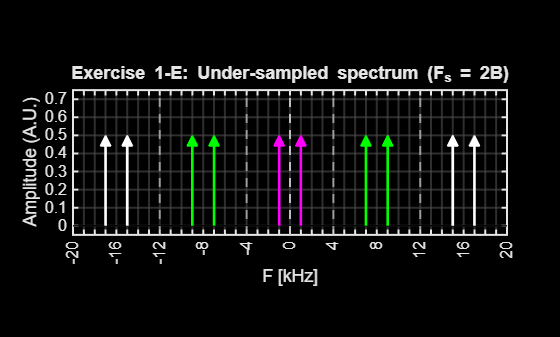


B     = B_default;            % 4 kHz
FsD   = 2*B;                  % 8 kHz
Fdata = Fdata_default;
Fcar  = Fcarrier_default;

% Original sidebands in kHz
F1k = (Fcar - Fdata)/1000;    % 15 kHz
F2k = (Fcar + Fdata)/1000;    % 17 kHz
Fs_khz = FsD/1000;            % 8 kHz

% All aliases from +/-15, +/-17 kHz within [-20, 20] kHz
alias_freqs_khz = [-17 -15 -9 -7 -1 1 7 9 15 17];

% All amplitudes are 0.5 (sum of two 0.25 contributions)
alias_amps = 0.5 * ones(size(alias_freqs_khz));

fig_e = plot_spectrum(alias_freqs_khz, alias_amps, ...
    'XRange', [-20 20], ...
    'XStep', 1, ...
    'MaxXLabels', 11, ...
    'YMax', 0.75, ...
    'YStep', 0.1, ...
    'MaxYLabels', 8, ...
    'XLabel', 'F [kHz]', ...
    'YLabel', 'Amplitude (A.U.)', ...
    'Title', 'Exercise 1-E: Under-sampled spectrum (F_s = 2B)', ...
    'Colors', {{'w'},{'w'}, {'g'},{'g'}, {'m'},{'m'}, {'g'},{'g'}, {'w'},{'w'}});

figure(fig_e); hold on;

centers_khz = [0,  FsD/2,  1.5*FsD] / 1000;
for c = centers_khz
    xline( c, '--', 'LineWidth', 1.5, 'Color', [0.8 0.8 0.8]);
    xline(-c, '--', 'LineWidth', 1.5, 'Color', [0.8 0.8 0.8]);
end

hold off;



if saveFigs
    exportgraphics(fig_e, fullfile(imgDir, ...
        'DSP_U12_Torsdag_1E_under_sampled_spectrum.png'), 'Resolution', 300);
end

## Exercise 1-F: Very high sampling frequency (no aliasing)

fprintf('Exercise 1-F:\n');

Exercise 1-F:



Fdata    = Fdata_default;
Fcarrier = Fcarrier_default;

Fs1    = Fcarrier * 100;    % 1.6 MHz
Ts1    = 1/Fs1;
deltaf = 50;                % 50 Hz resolution
N1     = Fs1 / deltaf;      % integer

fprintf('  Fs1 (high) = %.0f Hz\n', Fs1);

  Fs1 (high) = 1600000 Hz


fprintf('  N1         = Fs1/deltaf = %.0f samples\n\n', N1);

  N1         = Fs1/deltaf = 32000 samples



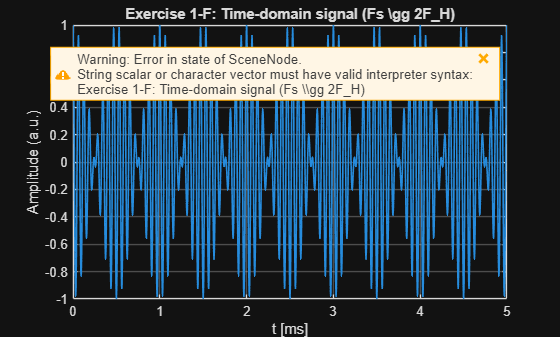


t1  = (0:N1-1) * Ts1;
xa1 = cos(2*pi*Fdata.*t1) .* cos(2*pi*Fcarrier.*t1);

% Time-domain (first 5 ms)
figure;
plot(t1*1e3, xa1, 'LineWidth', 1.2); grid on;
xlim([0 5]);
xlabel('t [ms]');
ylabel('Amplitude (a.u.)');
title('Exercise 1-F: Time-domain signal (Fs \gg 2F_H)');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir,'DSP_U12_Torsdag_1F_time_signal.png'),'Resolution',300);
end

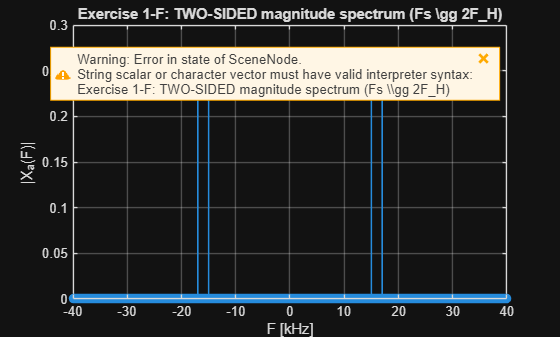


% Spectrum
XA1    = fft(xa1, N1);
XA1_sh = fftshift(XA1);
f1     = (-N1/2:N1/2-1) * (Fs1/N1);

figure;
stem(make_khz(f1), abs(XA1_sh)/N1, 'filled', 'LineWidth', 1.2); grid on;
xlabel('F [kHz]');
ylabel('|X_a(F)|');
title('Exercise 1-F: TWO-SIDED magnitude spectrum (Fs \gg 2F_H)');
xlim([-40 40]);

if saveFigs
    exportgraphics(gcf, fullfile(imgDir,'DSP_U12_Torsdag_1F_mag_spectrum_twosided.png'),'Resolution',300);
end

## Exercise 1-G: Under-sampling at Fs = 2B, m = 5 (odd)

fprintf('Exercise 1-G:\n');

Exercise 1-G:



Fdata    = Fdata_default;
Fcarrier = Fcarrier_default;
B        = B_default;

Fs2    = 2*B;          % 8 kHz
Ts2    = 1/Fs2;
deltaf = 50;
N2     = Fs2 / deltaf;

fprintf('  Fs2 = 2B = %.0f Hz\n', Fs2);

  Fs2 = 2B = 8000 Hz


fprintf('  N2  = Fs2/deltaf = %.0f samples\n\n', N2);

  N2  = Fs2/deltaf = 160 samples



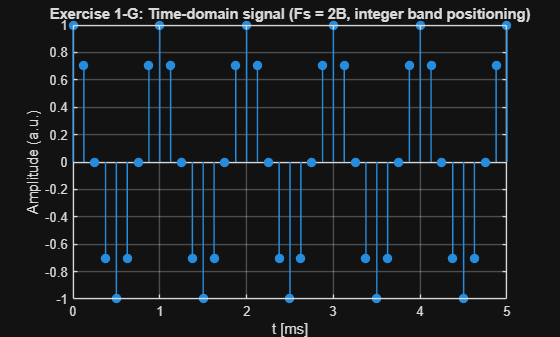


t2  = (0:N2-1) * Ts2;
xa2 = cos(2*pi*Fdata.*t2) .* cos(2*pi*Fcarrier.*t2);

% Time-domain
figure;
stem(t2*1e3, xa2, 'filled', 'LineWidth', 1.1); grid on;
xlim([0 5]);
xlabel('t [ms]');
ylabel('Amplitude (a.u.)');
title('Exercise 1-G: Time-domain signal (Fs = 2B, integer band positioning)');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir,'DSP_U12_Torsdag_1G_time_signal.png'),'Resolution',300);
end

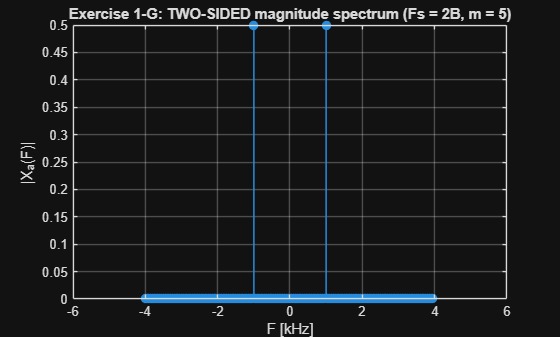


% Spectrum
XA2    = fft(xa2, N2);
XA2_sh = fftshift(XA2);
f2     = (-N2/2:N2/2-1) * (Fs2/N2);

figure;
stem(make_khz(f2), abs(XA2_sh)/N2, 'filled', 'LineWidth', 1.1); grid on;
xlabel('F [kHz]');
ylabel('|X_a(F)|');
title('Exercise 1-G: TWO-SIDED magnitude spectrum (Fs = 2B, m = 5)');
xlim([-6 6]);

if saveFigs
    exportgraphics(gcf, fullfile(imgDir,'DSP_U12_Torsdag_1G_mag_spectrum_twosided.png'),'Resolution',300);
end

## Exercise 1-H: Fs = 2.25B (non-integer valid region)

fprintf('Exercise 1-H:\n');

Exercise 1-H:



Fdata    = Fdata_default;
Fcarrier = Fcarrier_default;
B        = B_default;

Fs3    = 2*B + 0.25*B;       % 9 kHz
Ts3    = 1/Fs3;
deltaf = 50;
N3     = Fs3 / deltaf;

fprintf('  Fs3 = 2.25B = %.0f Hz\n', Fs3);

  Fs3 = 2.25B = 9000 Hz


fprintf('  N3  = Fs3/deltaf = %.0f samples\n', N3);

  N3  = Fs3/deltaf = 180 samples


fprintf('  This Fs does not satisfy integer band positioning; baseband looks scrambled.\n\n');

  This Fs does not satisfy integer band positioning; baseband looks scrambled.



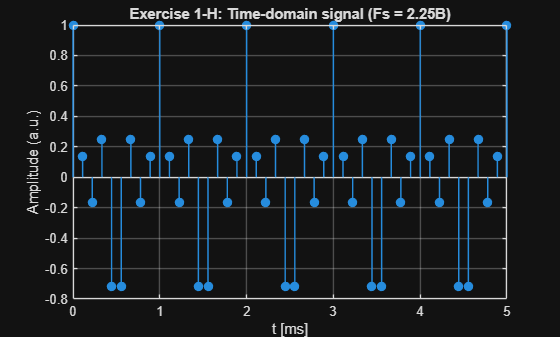


t3  = (0:N3-1) * Ts3;
xa3 = cos(2*pi*Fdata.*t3) .* cos(2*pi*Fcarrier.*t3);

% Time-domain
figure;
stem(t3*1e3, xa3, 'filled', 'LineWidth', 1.1); grid on;
xlim([0 5]);
xlabel('t [ms]');
ylabel('Amplitude (a.u.)');
title('Exercise 1-H: Time-domain signal (Fs = 2.25B)');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir,'DSP_U12_Torsdag_1H_time_signal.png'),'Resolution',300);
end

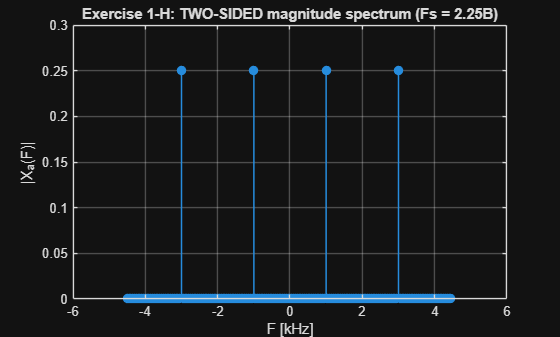


% Spectrum
XA3    = fft(xa3, N3);
XA3_sh = fftshift(XA3);
f3     = (-N3/2:N3/2-1) * (Fs3/N3);

figure;
stem(make_khz(f3), abs(XA3_sh)/N3, 'filled', 'LineWidth', 1.1); grid on;
xlabel('F [kHz]');
ylabel('|X_a(F)|');
title('Exercise 1-H: TWO-SIDED magnitude spectrum (Fs = 2.25B)');
xlim([-6 6]);

if saveFigs
    exportgraphics(gcf, fullfile(imgDir,'DSP_U12_Torsdag_1H_mag_spectrum_twosided.png'),'Resolution',300);
end

## Exercise 1-I: Fs = 2B, Fcarrier = 12 kHz (even m -> inverted)

fprintf('Exercise 1-I:\n');

Exercise 1-I:



Fdata    = Fdata_default;
Fcarrier = 12000;       % new carrier
B        = B_default;

Fs4    = 2*B;           % 8 kHz
Ts4    = 1/Fs4;
deltaf = 50;
N4     = Fs4 / deltaf;

FL_new = Fcarrier;
FH_new = FL_new + B;
m_new  = FH_new / B;

fprintf('  New carrier F_carrier = %.0f Hz\n', Fcarrier);

  New carrier F_carrier = 12000 Hz


fprintf('  B = %.0f Hz, FL = %.0f Hz, FH = %.0f Hz\n', B, FL_new, FH_new);

  B = 4000 Hz, FL = 12000 Hz, FH = 16000 Hz


fprintf('  Fs4 = 2B = %.0f Hz, N4 = %.0f\n', Fs4, N4);

  Fs4 = 2B = 8000 Hz, N4 = 160


fprintf('  m = FH/B = %.1f (even) --> inverted baseband alias.\n\n', m_new);

  m = FH/B = 4.0 (even) --> inverted baseband alias.



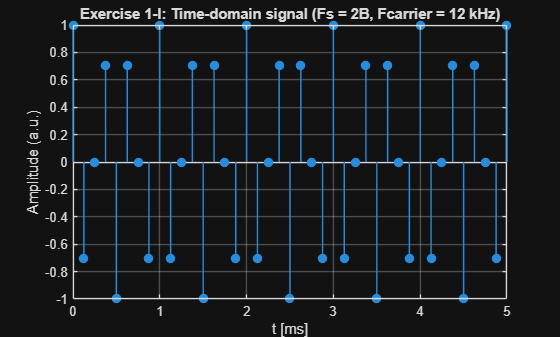


t4  = (0:N4-1) * Ts4;
xa4 = cos(2*pi*Fdata.*t4) .* cos(2*pi*Fcarrier.*t4);

% Time-domain
figure;
stem(t4*1e3, xa4, 'filled', 'LineWidth', 1.1); grid on;
xlim([0 5]);
xlabel('t [ms]');
ylabel('Amplitude (a.u.)');
title('Exercise 1-I: Time-domain signal (Fs = 2B, Fcarrier = 12 kHz)');

if saveFigs
    exportgraphics(gcf, fullfile(imgDir,'DSP_U12_Torsdag_1I_time_signal.png'),'Resolution',300);
end

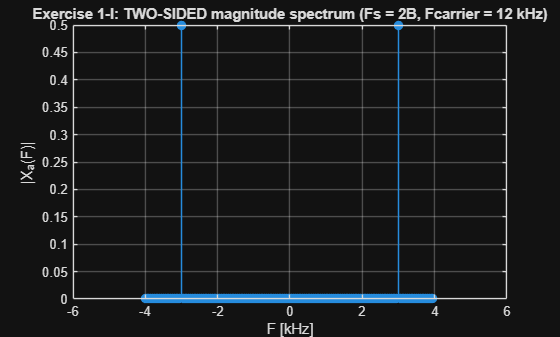


% Spectrum
XA4    = fft(xa4, N4);
XA4_sh = fftshift(XA4);
f4     = (-N4/2:N4/2-1) * (Fs4/N4);

figure;
stem(make_khz(f4), abs(XA4_sh)/N4, 'filled', 'LineWidth', 1.1); grid on;
xlabel('F [kHz]');
ylabel('|X_a(F)|');
title('Exercise 1-I: TWO-SIDED magnitude spectrum (Fs = 2B, Fcarrier = 12 kHz)');
xlim([-6 6]);

if saveFigs
    exportgraphics(gcf, fullfile(imgDir,'DSP_U12_Torsdag_1I_mag_spectrum_twosided.png'),'Resolution',300);
end


fprintf('Done: all sub-exercises 1-A ... 1-I evaluated.\n');

Done: all sub-exercises 1-A ... 1-I evaluated.
